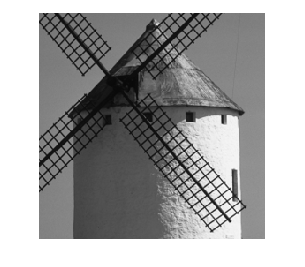

%imwrite(b11, ’b11.tif’, ’Resolution’, 150);
%Kommandot sparar bilden med upplösningen 150 dots (eller pixlar)/tum 
% i tif format
clear;
kvarn = imread('kvarn.tif');
kvarn = im2double(kvarn);
imshow(kvarn);

% 1.1 
b11 = (kvarn >= 0.5)

b11 = 512×512 logical array
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0

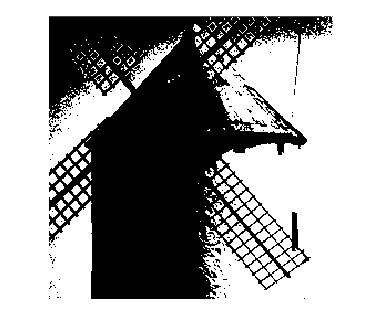

imshow(b11)

imwrite(b11, 'b11.tif', 'Resolution', 150);

% 1.2
load('troskelmatriser.mat')
max(max(tr1))

ans = 18

max(max(tr2))

ans = 32

tr1 = tr1/19

tr1 =     0.4737    0.3684    0.4211    0.5263    0.6316    0.5789
    0.3158    0.0526    0.1053    0.6842    0.9474    0.8947
    0.2632    0.2105    0.1579    0.7368    0.7895    0.8421
    0.5263    0.6316    0.5789    0.4737    0.3684    0.4211
    0.6842    0.9474    0.8947    0.3158    0.0526    0.1053
    0.7368    0.7895    0.8421    0.2632    0.2105    0.1579


tr2 = tr2/33

tr2 =     0.4242    0.3636    0.3939    0.4848    0.5758    0.6364    0.6061    0.5152
    0.1515    0.1212    0.0909    0.3030    0.8485    0.8788    0.9091    0.6970
    0.1818    0.0303    0.0606    0.3333    0.8182    0.9697    0.9394    0.6667
    0.2727    0.2121    0.2424    0.4545    0.7273    0.7879    0.7576    0.5455
    0.5758    0.6364    0.6061    0.5152    0.4242    0.3636    0.3939    0.4848
    0.8485    0.8788    0.9091    0.6970    0.1515    0.1212    0.0909    0.3030
    0.8182    0.9697    0.9394    0.6667    0.1818    0.0303    0.0606    0.3333
    0.7273    0.7879    0.7576    0.5455    0.2727    0.2121    0.2424    0.4545


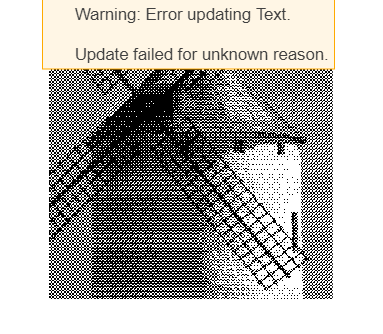

b12_tr1 = troskel(kvarn, tr1);
imshow(b12_tr1)

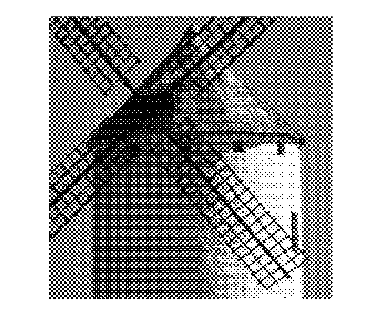

b12_tr2 = troskel(kvarn, tr2);
imshow(b12_tr2)

imwrite(b12_tr1, 'b12_tr1.tif', 'Resolution', 150);
imwrite(b12_tr2, 'b12_tr2.tif', 'Resolution', 150);

% 1.3
max(max(tr3))
tr3 = tr3/33

tr3 =     0.0303    0.9091    0.2424    0.8485    0.0606    0.8788    0.2121    0.8182
    0.5152    0.2727    0.7273    0.4848    0.5455    0.3030    0.6970    0.4545
    0.1515    0.7576    0.0909    0.9697    0.1818    0.7879    0.1212    0.9394
    0.6364    0.3939    0.5758    0.3333    0.6667    0.4242    0.6061    0.3636
    0.0606    0.8788    0.2121    0.8182    0.0303    0.9091    0.2424    0.8485
    0.5455    0.3030    0.6970    0.4545    0.5152    0.2727    0.7273    0.4848
    0.1818    0.7879    0.1212    0.9394    0.1515    0.7576    0.0909    0.9697
    0.6667    0.4242    0.6061    0.3636    0.6364    0.3939    0.5758    0.3333


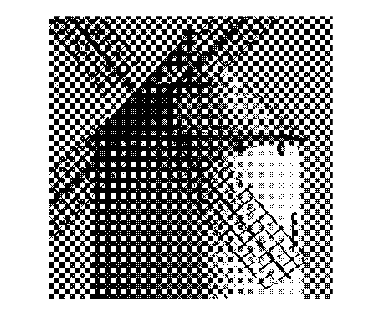

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.



b13 = troskel(kvarn, tr3);
imshow(b13)

imwrite(b13, 'b13.tif', 'Resolution', 150);

% 1.4
linje = [1, 2, 3, 4;
    5, 6, 7, 8;
    9, 10, 11, 12;
    13, 14, 15, 16]/17;
spiral = [10, 9, 8, 7;
        11, 2, 1, 6;
        12, 3, 4, 5;
        13, 14, 15, 16] / 17;

b14_linje = troskel(kvarn, linje)

b14_linje = 512×512 logical array
   1   1   1   1   1   1   1   1   1   1   0   0   1   1   1   1   1   1   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   0   1   0   0   0   1   1   1   1   1   1
   1   1   1   0   1   1   1   0   1   0   0   0   1   0   0   0   0   0   0   0   1   0   1   0   1   1   1   0   1   1   1   0   1   1   0   0   0   0   0   0   0   0   0   0   0   0   1   0   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   1   0   0  

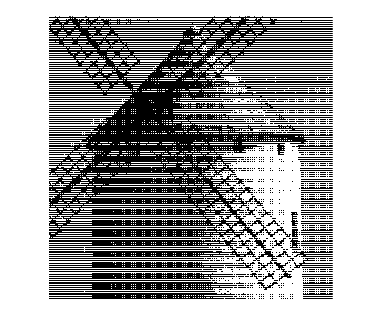

imshow(b14_linje)

imwrite(b14_linje, 'b14_linje.tif', 'Resolution', 150);

b14_spiral = troskel(kvarn, spiral)

b14_spiral = 512×512 logical array
   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0
   0   1   1   1   0   1   1   1   0   1   1   0   0   1   1   1   0   1   1   0   0   1   1   1   0   1   1   1   0   1   1   1   0   1   1   0   0   0   1   0   0   0   1   0   0   1   1   1   0   1
   0   1   1   1   0   1   1   1   0   1   1   0   0   0   0   0   0   0   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   0   0   0   0   0   0   0   0   0   1   0   0   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0 

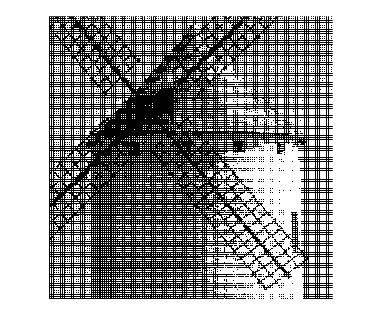

imshow(b14_spiral)

imwrite(b14_spiral, 'b14_spiral.tif', 'Resolution', 150);

% 2.1
b21 = tabellrast(kvarn)

b21 = 512×512 logical array
   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0
   1   1   1   0   1   1   1   0   0   1   1   0   0   1   1   0   0   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   0   1   0   0   0   1   0   0   0   1   1   0   1   1
   1   1   1   0   1   1   1   0   0   1   1   0   0   0   1   0   0   0   1   0   1   1   1   0   1   1   1   0   1   1   1   0   1   1   1   0   0   0   0   0   0   0   0   0   0   1   1   0   1   1
   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0

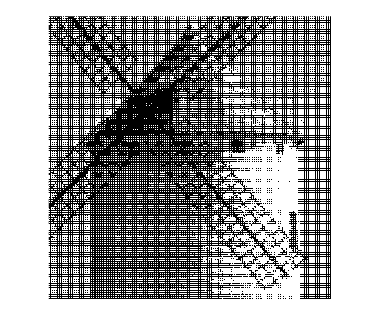

imshow(b21)

imwrite(b21, 'b21.tif', 'Resolution', 150);

% 2.2
b22 = tabellrast2(kvarn)

b22 = 512×512 logical array
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   0   0   1   0   1   0   1   0
   0   1   0   1   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1
   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   0   0   0   0   0   0   1   0   1   0   1   0
   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0

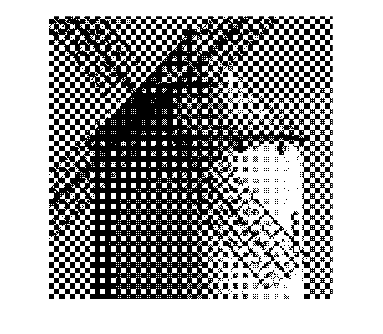

imshow(b22)

imwrite(b22, 'b22.tif', 'Resolution', 150);

% 2.3
b24 = tabellrast3(kvarn)

b24 = 1024×1024 logical array
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0
   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   0   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   1   0   1   0   1
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   0   0   1   0   1   0   1   0   1   0   0   0   1   0   0   0   1   0   1   0   1   0   1   0   1   0   1   0
   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0   0   0   0   0   0   0   0   0   0   0   0   0   0   1   0   0
   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   1   0   0   0   1   0   0   0   1   0   0   0   1   0   1   0   1  

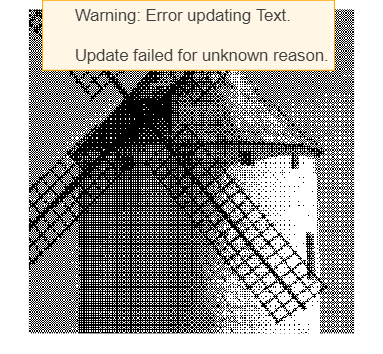

imshow(b24)

imwrite(b24, 'b24.tif', 'Resolution', 150);
whos b24

  Name         Size                Bytes  Class      Attributes

  b24       1024x1024            1048576  logical              



% 3.1
filt1 = [0 0 7;
        3 5 1]/16;
b31 = errordif(kvarn, filt1)

b31 =      0     1     0     1     0     1     0     1     0     0     0     0     0     0     1     0     0     0     0     0     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     0
     1     0     1     0     1     0     0     1     0     1     0     0     1     0     0     1     0     0     0     1     0     0     1     0     1     0     1     0     1     0     1     0     1     0     0     1     0     0     0     0     0     0     0     0     1     0     0     1     0     1
     0     1     0     0     1     0     1     0     1     0     0     0     0     0     0     0     0     1     0     0     1     0     1     0     0     1     0     0     1     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     1     0     1     0     1     0     1     0     1     0     1     0     0     0 

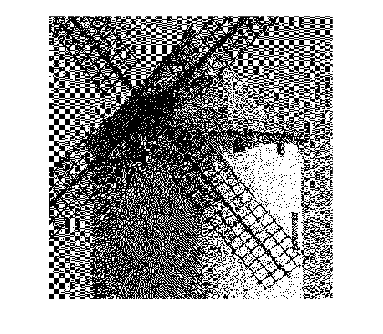

imshow(b31)

imwrite(b31, 'b31.tif', 'Resolution', 150);

% 3.2
filt2 =  [0 0 0 7 5;
        3 5 7 5 3;
        1 3 5 3 1]/48;
b32 = errordif(kvarn, filt2)

b32 =      0     1     0     0     1     0     0     1     0     0     0     0     0     0     0     1     0     0     0     0     0     0     1     0     0     1     0     0     1     0     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0
     1     0     1     0     1     1     0     1     0     0     0     0     1     0     1     0     0     0     0     0     1     0     1     1     0     1     1     0     1     1     0     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     1
     0     1     0     0     1     0     0     1     1     0     0     0     0     0     0     0     0     0     1     0     1     0     0     1     0     0     1     0     0     1     0     0     1     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     1     0     1     0     0     1     0     1     1     0     0     0     0     0 

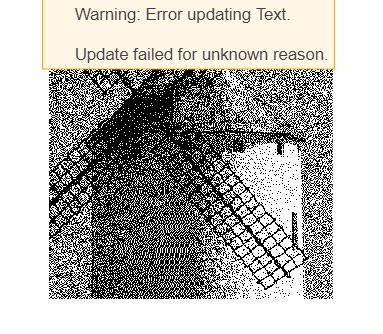

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.



imshow(b32)

imwrite(b32, 'b32.tif', 'Resolution', 150);

% 3.4
filt3 = [0;
        1];
filt4 = [0 0 1;
        0 1 0]/2;

b34_f3 = errordif(kvarn, filt3)

b34_f3 =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     1     1     1     1     1     1     1     1     1     1     0     0     1     1     1     1     0     0     0     0     1     1     1     1     1     1     1     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     1     1     1     1
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     1     0     0     0     0     0     0     0     0     1     1     0     0     0     0
     1     1     1     1     1     1     1     1     0     0     1     1     0     0    

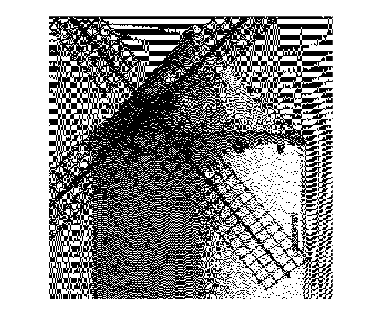

imshow(b34_f3)

imwrite(b34_f3, 'b34_f3.tif', 'Resolution', 150);

b34_f4 = errordif(kvarn, filt4)

b34_f4 =      0     1     0     1     0     1     0     1     0     0     0     0     0     1     0     0     0     0     0     0     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     0
     1     0     1     0     1     0     1     0     0     1     0     0     1     0     0     1     0     1     0     0     1     0     1     0     1     0     1     0     1     0     1     0     1     0     0     1     0     0     0     0     0     0     0     0     1     0     0     1     0     1
     0     1     0     1     0     1     0     0     1     0     0     1     0     0     0     0     0     0     0     1     0     1     0     1     0     1     0     0     1     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     0
     1     0     1     0     0     0     1     1     0     1     0     0     0     0    

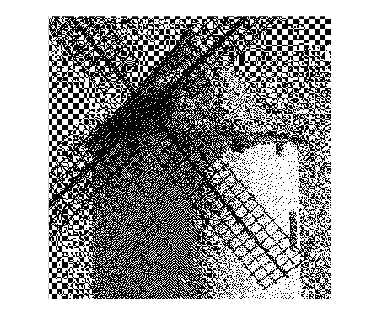

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.

Error using matlab.internal.editor.figure.WarningGraphicsIcon/setupTextBox
Error while evaluating HTMLCanvas ErrorCallback.



imshow(b34_f4)

imwrite(b34_f4, 'b34_f4.tif', 'Resolution', 150);

% 3.6
k = 0.4

k = 0.4000

noise = (rand(512, 512) - 0.5) * k

noise =     0.1259    0.0176   -0.1278    0.1846   -0.1004    0.1586   -0.0391   -0.0849    0.0758   -0.1860   -0.1873   -0.0156    0.0535   -0.0510   -0.1814    0.0925    0.1280   -0.1492    0.0343   -0.0524   -0.1619    0.1993    0.0664   -0.1066    0.1647    0.0522   -0.0654   -0.1587   -0.1070   -0.1277    0.1591    0.0806    0.1314    0.1363   -0.1489    0.1330    0.0259    0.0770   -0.0052   -0.0009    0.0275    0.0506   -0.1358    0.0156   -0.0360   -0.0524    0.1210    0.0429   -0.1294   -0.0994
    0.1623    0.0884   -0.1820    0.1050   -0.0097   -0.0071    0.1537   -0.1661   -0.1798   -0.0378    0.0900   -0.0543    0.1199   -0.0716   -0.1072   -0.1014   -0.0632    0.0396    0.1065   -0.1679    0.1871    0.1752    0.1893   -0.0768   -0.0609    0.0054    0.0192    0.1270   -0.1532   -0.1225    0.0605    0.0689    0.0517   -0.1082   -0.1154   -0.1958   -0.1817   -0.1581    0.0815    0.0549    0.1661    0.0809   -0.0394   -0.1956   -0.1435   -0.0307    0.0733   -0.1793    0.1305 

b36 = kvarn + noise

b36 =     0.5847    0.4764    0.3271    0.6395    0.3545    0.6135    0.4080    0.3621    0.3738    0.1120   -0.0854    0.0863    0.3476    0.2431    0.2265    0.5004    0.3124    0.0351    0.1598    0.0731    0.1832    0.5444    0.5253    0.3522    0.6235    0.5111    0.3934    0.3001    0.3479    0.3272    0.6180    0.5394    0.5941    0.5990    0.0864    0.3683    0.0965    0.1476    0.0615    0.0657    0.0902    0.1134   -0.0534    0.0979    0.1876    0.1711    0.5406    0.4625    0.3294    0.3594
    0.6211    0.5472    0.2729    0.5599    0.4452    0.4478    0.6008    0.2809    0.1182    0.2602    0.1919    0.0477    0.4140    0.2225    0.3007    0.3065    0.1211    0.2239    0.2320   -0.0424    0.5322    0.5203    0.6481    0.3820    0.3979    0.4642    0.4781    0.5858    0.3017    0.3324    0.5193    0.5278    0.5144    0.3546    0.1199    0.0395   -0.1111   -0.0875    0.1481    0.1216    0.2289    0.1437    0.0429   -0.1133    0.0801    0.1928    0.4929    0.2403    0.5893   

b36 = errordif(b36, filt1)

b36 =      1     0     0     1     0     1     0     0     1     0     0     0     0     0     0     1     0     0     0     0     0     1     0     1     0     1     0     0     1     0     1     0     1     0     0     1     0     0     0     0     0     0     0     0     0     0     1     0     0     1
     1     1     0     1     0     1     1     0     0     0     0     0     1     0     1     0     0     0     1     0     0     1     1     0     0     1     0     1     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     0
     0     0     1     0     0     0     1     0     1     0     0     0     0     0     0     0     0     0     0     0     1     0     0     1     0     1     0     1     0     1     0     0     1     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     1
     1     1     0     1     1     0     0     1     0     1     0     0     1     0     0 

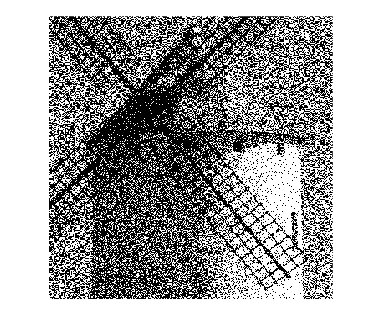

imshow(b36)

imwrite(b36, 'b36.tif', 'Resolution', 150);

% 4
b40 = imcdp(kvarn)

imcdp
----------
here13
here14
here14
9% done
----
17% done
----
26% done
----
34% done
----
43% done
----
52% done
----
60% done
----
69% done
----
78% done
----
86% done
----
95% done
----
here9
here10
here8
here17
here7
here6
here18
here5
here4
here3
here11
here2
here15
here12
here16
here1


b40 =      0     0     0     0     0     0     0     0     0     0     0     1     1     1     1     1     1     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     0     1     0     1     0     1     1     1     0     1     1     0     1     1     1     0     1     0
     0     1     0     1     0     1     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     1     0     1     0     1     0     1     0     1     1     0     1     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     1     0
     0     1     0     1     0     1     0     1     1     0     1     0     0     0     0     0     0     0     0     1     0     1     1     0     1     0     1     0     1     0     0     1     1     1     0     1     0     0     0     0     0     0     0     0     0     0     0     1     0     0
     0     0     0     1     0     1     0     0     1     0     0     0     1     0     0 

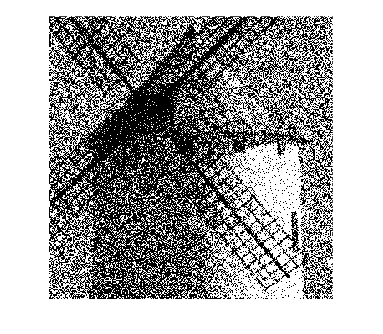

imshow(b40)

imwrite(b40, 'b40.tif', 'Resolution', 150);

% 5.1
SNRb11 = mysnr(kvarn, kvarn - b11)

SNRb11 = 2.5915

SNRb31 = mysnr(kvarn, kvarn - b31)

SNRb31 = 0.8801

SNRb40 = mysnr(kvarn, kvarn - b40)

SNRb40 = 0.8062

% 5.2
SNRfilterb11 = snr_filter(kvarn, kvarn - b11)

SNRfilterb11 = 2.9988

SNRfilterb31 = snr_filter(kvarn, kvarn - b31)

SNRfilterb31 = 13.9621

SNRfilterb40 = snr_filter(kvarn, kvarn - b40)

SNRfilterb40 = 12.0117

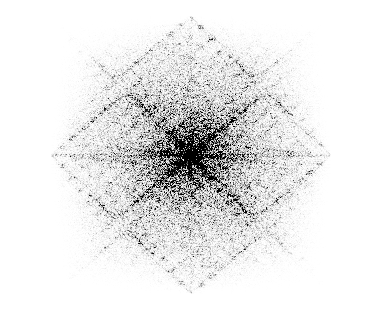

% 5.3
QNSb11 = QNS(kvarn, b11);

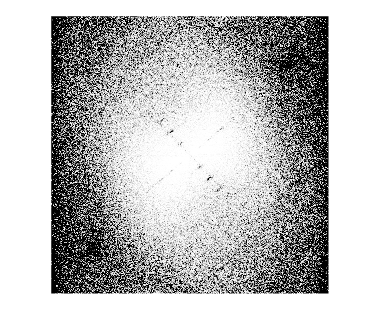

QNSb31 = QNS(kvarn, b31);

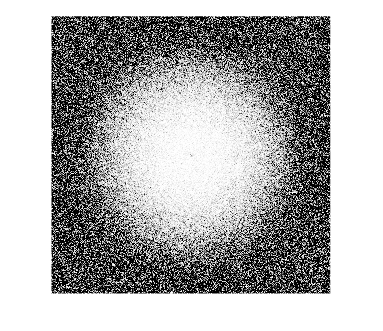

QNSb40 = QNS(kvarn, b40);

imwrite(QNSb11, 'QNSb11.tif', 'Resolution', 150);
imwrite(QNSb31, 'QNSb31.tif', 'Resolution', 150);
imwrite(QNSb40, 'QNSb40.tif', 'Resolution', 150);

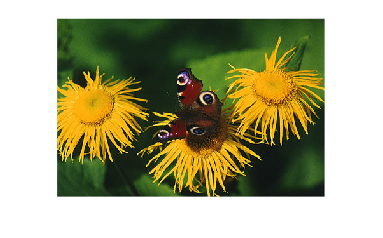

% Del 3
musicians = im2double(imread('musicians.tif'));
butter = im2double(imread('butterfly.tif'));

imshow(butter)

imgButter = fargraster(butter, 'imcdp');

imcdp
----------
23% done
----
47% done
----
here14
here14
70% done
----
here13
here12
94% done
----
here11
here16
here17
here6
here4
here9
here7
here5
here8
here15
here18
here3
here10
here2
here1
imcdp
----------
here14
24% done
----
48% done
----
here14
here16
here12
here13
72% done
----
here11
96% done
----
here10
here9
here7
here6
here8
here4
here5
here3
here18
here2
here15
here1
here17
imcdp
----------
here15
here16
here17
here4
here3
here2
here14
here8
88% done
----
88% done
----
here9
here7
here6
here18
here14
here10
here12
here13
here11
here5
here1


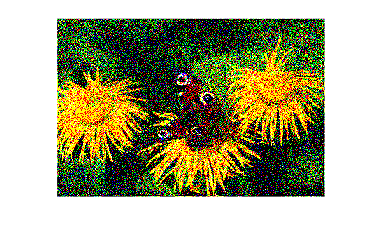

imshow(imgButter)

imgButter = fargraster(butter, 'majs');

Måste använda errordif eller IMCDP


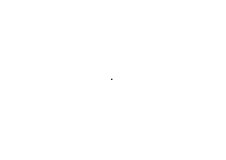

imshow(imgButter)

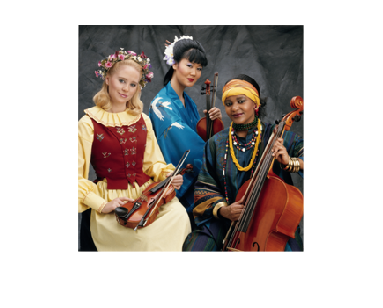


imshow(musicians)

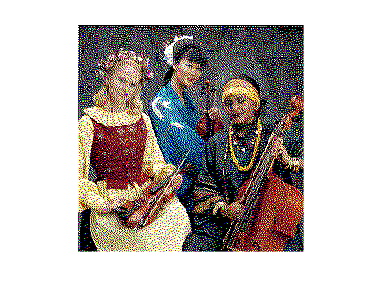

imgMusic = fargraster(musicians, 'errordif');
imshow(imgMusic)